Import the urdf file for Mover6

clc
mover6 = importrobot('CPMOVER6.urdf')

mover6 =   rigidBodyTree with properties:

     NumBodies: 6
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'link1'  'link2'  'link3'  'link4'  'link5'  'link6'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'


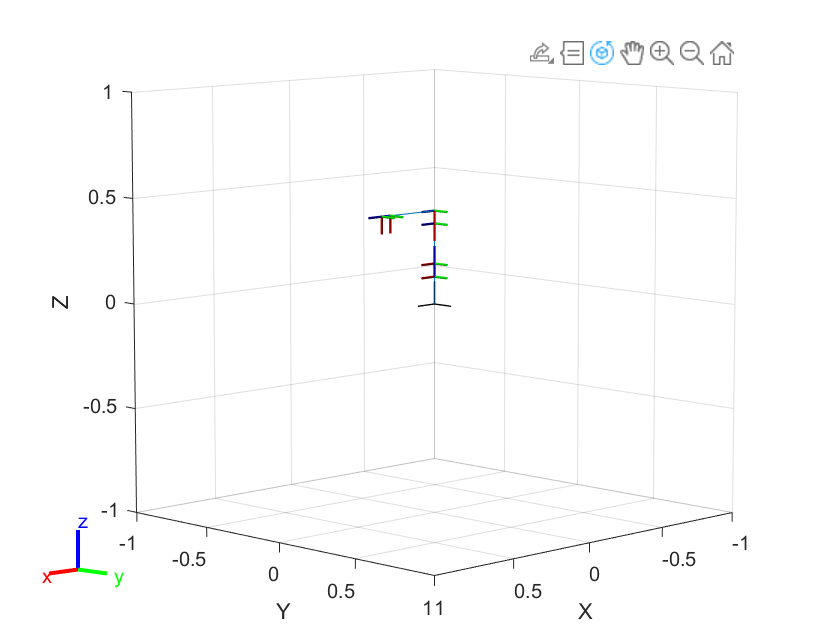

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


mover6.show

Transform matrix

tform_homeConfig = getTransform(mover6, mover6.homeConfiguration, 'link6', 'base_link')

tform_homeConfig =     0.0000         0    1.0000    0.3450
         0    1.0000         0         0
   -1.0000         0    0.0000    0.4425
         0         0         0    1.0000


Inverse kinematics:

Set a random configuration for the arm:

randConfig = mover6.randomConfiguration

randConfig = 1×6 struct array with fields:
    JointName
    JointPosition


tform = getTransform(mover6, randConfig, 'link6', 'base_link')

tform =    -0.1655   -0.2164    0.9622    0.3001
    0.9187   -0.3886    0.0706    0.0253
    0.3586    0.8956    0.2632    0.4812
         0         0         0    1.0000


View the arm in the random configuration

figure()
show(mover6, randConfig)

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


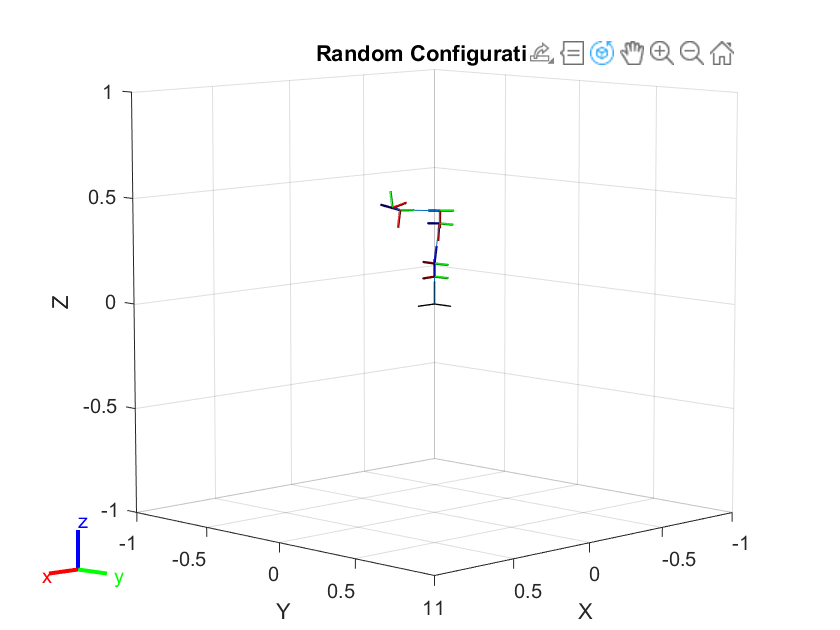

title("Random Configuration")

ik = inverseKinematics('RigidBodyTree', mover6)

ik =   inverseKinematics with properties:

       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


ik.SolverParameters

ans = struct with fields:
         MaxIterations: 1500
               MaxTime: 10
     GradientTolerance: 1.0000e-07
     SolutionTolerance: 1.0000e-06
    EnforceJointLimits: 1
    AllowRandomRestart: 1
         StepTolerance: 1.0000e-14


Let’s specify a weights vector that specifies the relative importance of the pose and position

weights = [0.25 0.25 0.25 1 1 1];

Set an initial guess. Using home configuration as the initial guess.

initialGuess = mover6.homeConfiguration;
[configSol, solnInfo] = ik('link6', tform, weights, initialGuess)

configSol = 1×6 struct array with fields:
    JointName
    JointPosition


solnInfo = struct with fields:
           Iterations: 38
    NumRandomRestarts: 0
        PoseErrorNorm: 5.7654e-10
             ExitFlag: 1
               Status: 'success'



figure()
show(mover6, configSol)

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


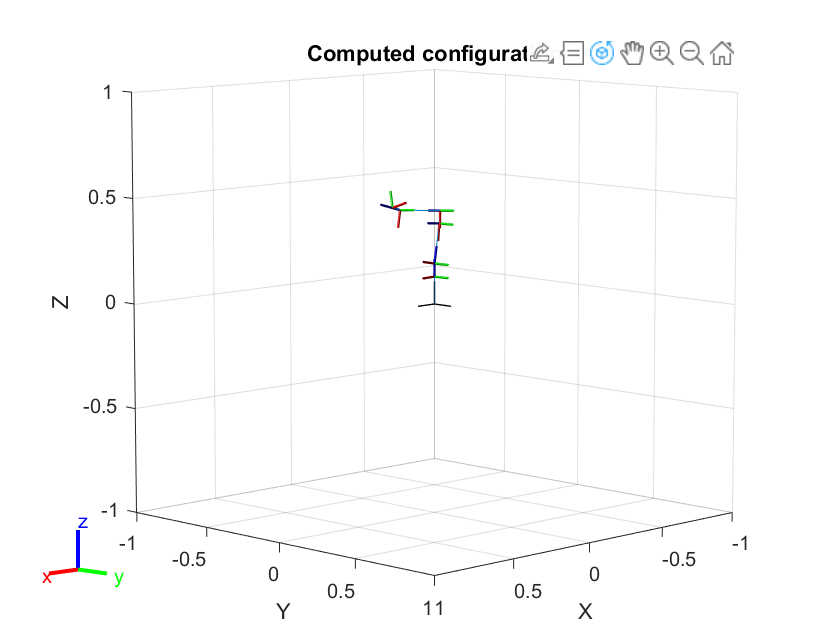

title("Computed configuration")